 
startup('Robot1');

Khởi động hệ thống cho robot: Robot1...
Chương trình đã khởi động thành công.


% Parameters
% P1 = Point([1, 1, 1], [1, 0, 0, 0], 'World');
% P2 = Point([1, 2.51, 3.123], [0, 1, 0, 0], 'World');
% P3 = Point([1, 2, 3.123], [0, 1, 0, 0], 'World');
% a = MoveCircle(P1,P2,P3,0,1.2231,0,0)
% plotTrajectory(a.PointTrajectory,a.VelocityTrajectory,a.AccelerationTrajectory,a.OrientationTrajectory,a.TimeTrajectory);

File "points.txt" has been created or overwritten in the "data" directory with 10 points.


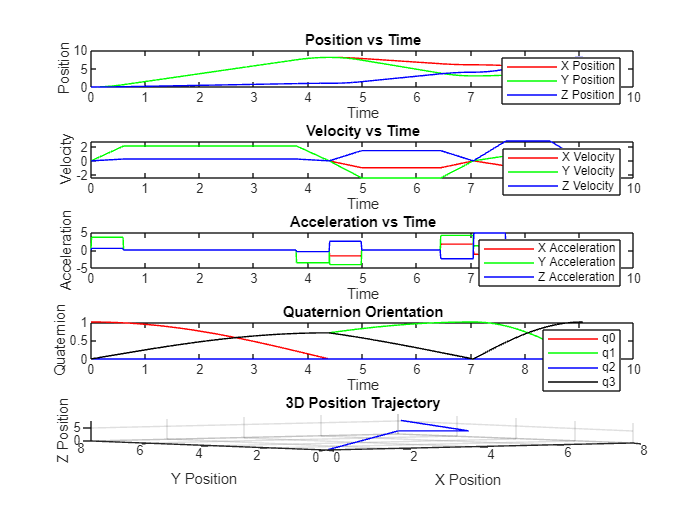

% Khởi tạo điểm ngẫu nhiên
generatePointsFile(10, 0, [0 10]);

% Khởi tạo đối tượng TrajectoryPlanner
planner = TrajectoryPlanner();

% Đọc các điểm từ tệp points.txt
planner.readPoints('points.txt');

% Đọc và xử lý các lệnh di chuyển từ tệp commands.txt
planner.processCommands('commands.txt');

% Vẽ quỹ đạo
planner.plotTrajectory();


% plot3DTrajectoryWithQuaternions(a.PointTrajectory,a.OrientationTrajectory);
cleanup();

Đang kết thúc chương trình...
Chương trình đã kết thúc thành công.


function plotArrayData(data)
    figure; % Tạo một hình mới
    plot(data); % Vẽ biểu đồ dữ liệu từ mảng data
    xlabel('Index'); % Đặt nhãn trục x
    ylabel('Value'); % Đặt nhãn trục y
    title('Plot of Array Data'); % Đặt tiêu đề biểu đồ
    grid on; % Bật lưới
end
